# Pendulum Eigenvalue Demonstration Code

Team 14 - Embreeyos 

## Loading Video

clear;
vid = VideoReader('demo.mp4');
totalFrames = vid.NumFrames;

k = 2; % NUMBER OF MASSES

## Turn Slider Until Mass Swinging Begins

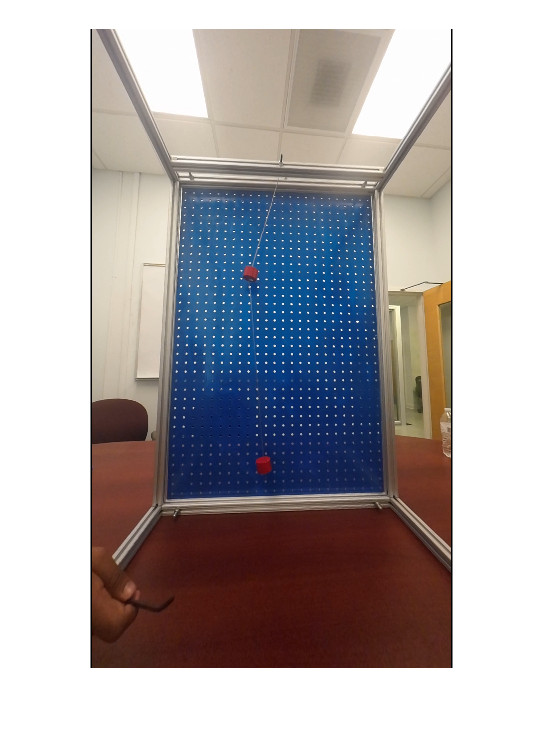

startIndex = 2421;
pic = vid.read(startIndex);
figure()
imshow(pic);

## Turn Sliders Until Only the Backing and Masses are in-frame 

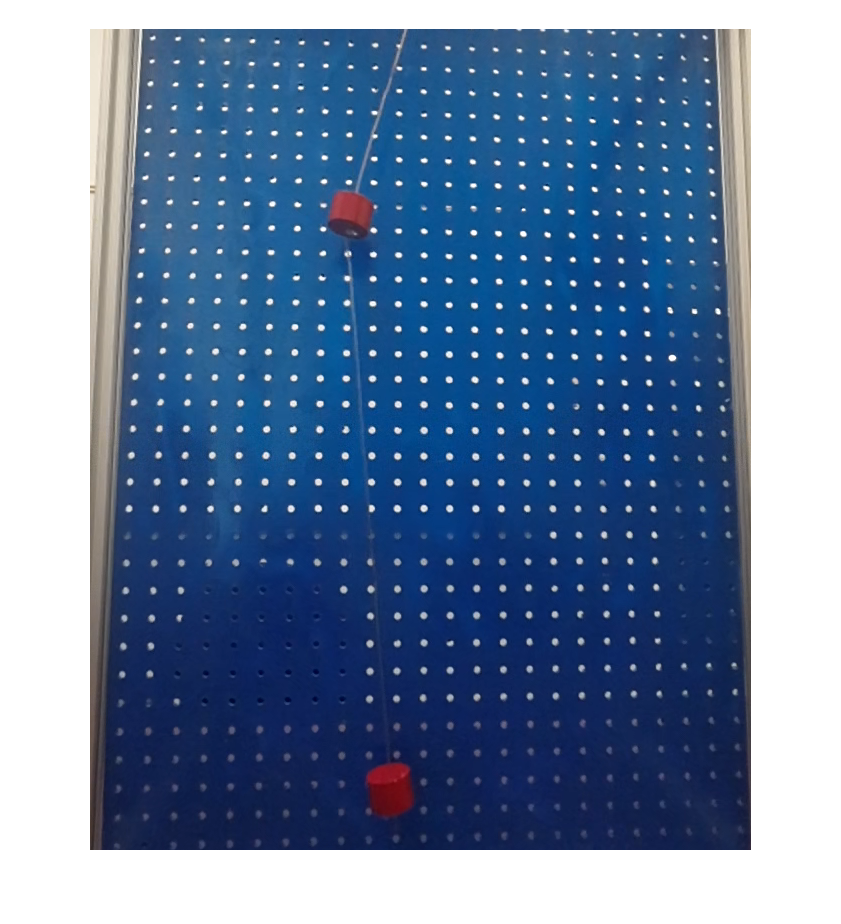

pic = vid.read(startIndex); % Loading the starting Frame


maxRow = size(pic,1); % Maximum Row of the frame
maxCol = size(pic, 2); % Maximum Column of the frame


% Sliders to adjust the left, right, upper and lower bounds to crop the
% masses
leftBound = 221;
rightBound = 881;
lowerBound = 1371;
upperBound = 551;

% Cropping the frame
pic = pic(upperBound:lowerBound, leftBound:rightBound, :);

figure;
imshow(pic);

## Turn Sliders Until Only the Masses are Visible

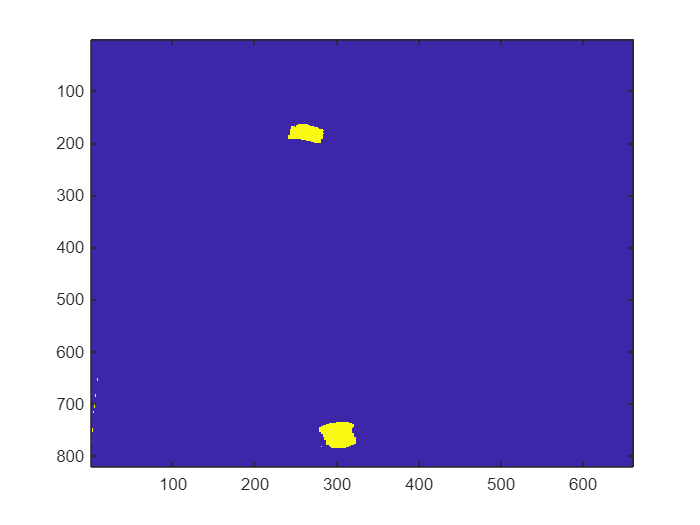

% Isolating Red, Green, and Blue Layers of the frame
r = pic(:,:,1);
g = pic(:,:,2);
b = pic(:,:,3);

% Thresholds for isolating the red masses 
red_thresh =   86;
blue_thresh =  150;
green_thresh =   75;
r(r < red_thresh) = 0;
r(b > blue_thresh) = 0;
r(g > green_thresh) = 0;

% Creating a binary color palette
r(r > 0) = 1;

figure()
imagesc(r);

## Initializing KMeans to Determine Centers (Retry Until Convergence)

[rows, cols] = find(r); % Convert data to indices of non-zero entries

% Create output matrix
X = zeros(length(rows), 2);
X(:, 1) = rows;
X(:, 2) = cols;

% Set up k-means algorithm

% Set Options for KMeans Clustering
opts = statset('Display','final'); 

% Run One Iteration of KMeans Clustering
[idx,C] = kmeans(X,k,'Options',opts);

Replicate 1, 1 iterations, total sum of distances = 4.223e+06.
Best total sum of distances = 4.223e+06


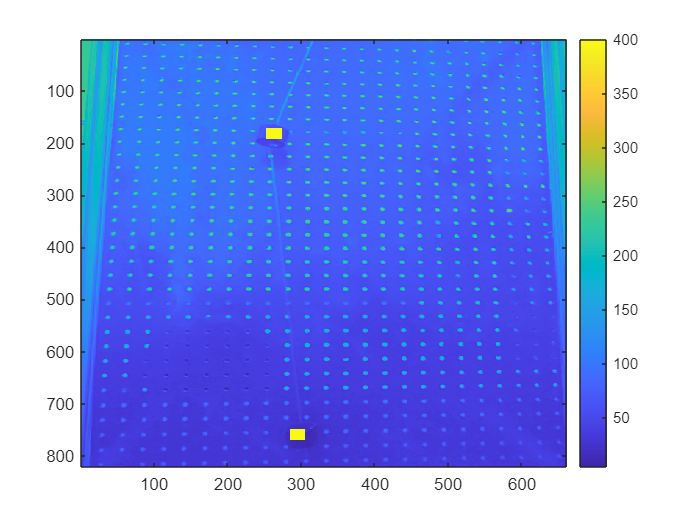

% Convert cluster centers to row and column coordinates
[rows,cols] = ind2sub(size(r),C);

% Creating a test picture to display
testPic = uint16(g); 

% Plotting squares to determine where the K-Means 
for i = 1:size(C,1)
    x = round(C(i,1));
    y = round(C(i,2));
    if (x < 11)
        x = 11; 
    end 
    if (x > size(testPic,1) - 11)
        x = size(testPic,1) - 11;
    end

    if (y < 11)
        y = 11; 
    end 
    if (y > size(testPic,2) - 11)
        y = size(testPic,2) - 11;
    end
    
    testPic(x-10:x+10, y-10:y+10) = 400;
end

figure()
imagesc(testPic); colorbar;

## Running K-Means to Convert to Time Series

tic 
TSeries = zeros(vid.NumFrames, k);

opts = statset('Display','off','MaxIter',1,'UseParallel',false);

figure()

% Boolean variable if you want to plot each frame (slower)
plotFigure = false;

for i = startIndex:vid.NumFrames
    warning('off', 'all');
    pic = vid.read(i);

    pic = pic(upperBound:lowerBound, leftBound:rightBound, :);

    r = pic(:,:,1);
    g = pic(:,:,2);
    b = pic(:,:,3);

    r(r < red_thresh) = 0;
    r(b > blue_thresh) = 0;
    r(g > green_thresh) = 0;
    
    r(r > 0) = 1;

    [rows, cols] = find(r); % Convert data to indices of non-zero entries
    
    % Set up k-means algorithm
    
    [~,C] = kmeans([rows cols],k,'Options',opts, 'Display','off','Start', C);
    TSeries(i,:) = round(C(:,2))';

    
    
    if (plotFigure == true)
    
        testPic = uint16(g); 
        for j = 1:size(C,1)
            x = round(C(j,1));
            y = round(C(j,2));
            if (x < 11)
                x = 11; 
            end 
            if (x > size(testPic,1) - 11)
                x = size(testPic,1) - 11;
            end
        
            if (y < 11)
                y = 11; 
            end 
            if (y > size(testPic,2) - 11)
                y = size(testPic,2) - 11;
            end
        
            testPic(x-10:x+10, y-10:y+10) = 400;
        end

        imagesc(testPic); colorbar; title(sprintf("Iteration %d of %d", i, vid.NumFrames)); drawnow;
    end
        %fprintf("Frame %d of %d\n", i, vid.numFrames);
    %end
    
    
    
end

toc

Elapsed time is 174.029194 seconds.


## Testing Continuity of Time Series

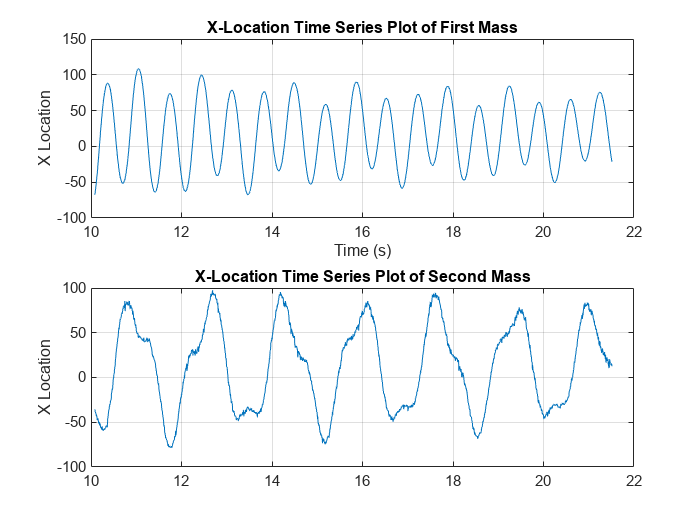

figure()
n = vid.NumFrames;
dt = 1/240; % Setting timestep (240 Hz)
t_end = dt*n; 
t = linspace(0,t_end, n); % Creating t-vector

TSeries = TSeries - size(r,2)/2; % Moving to the middle axis
TSeriesTrimmed = TSeries(startIndex:end,:); % Trimming to exclude the frames before KMeans is executed

% Plotting the time-series
figure()
subplot(2,1,2)
plot(t(startIndex:end), TSeriesTrimmed(:,1)); hold on;
grid on; 
ylabel("X Location");
title("X-Location Time Series Plot of Second Mass")
subplot(2,1,1)

plot(t(startIndex:end), TSeriesTrimmed(:,2));
grid on;
title("X-Location Time Series Plot of First Mass")
xlabel("Time (s)");
ylabel("X Location");
print('TimeSeries.png', '-dpng', '-r300');

## Performing Fourier Transformation on Time-Series Data

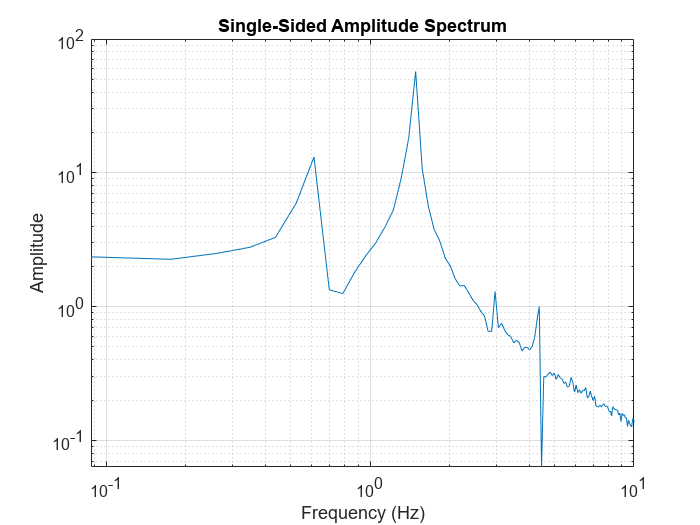

% Create test signal
fs = 240; % Sampling rate
t = 0:1/fs:1-1/fs; % Time vector

x = TSeriesTrimmed(:,2)'; % Extracting the vector of interest 

% Perform FFT
N = length(x);
X = fft(x)/N; % Normalize by N to get correct amplitude
f = (0:N-1)*(fs/N); % Frequency vector
X_pos = X(1:N/2+1); % Positive side of frequency spectrum
f_pos = f(1:N/2+1); % Positive side of frequency vector

% Plot frequency response
figure();
loglog(f_pos(2:end),2*abs(X_pos(2:end)));
xlim([0 10]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Single-Sided Amplitude Spectrum');
print('ExampleFFT.png', '-dpng', '-r300');

## Theoretical Validation

% Masses and Lengths between masses 
ms = [0.260 0.260]'; % kg
ls = [0.343 0.508]'; % m 

% Creating the forces on each mass
sigmas = zeros(size(ms));

for i = 1:length(ms)
    sigmas(i) = 9.81*sum(ms(1:i));
end

% Generating M and K matrices
M = diag(ms);

K = zeros(size(M));

lowerDiag = sigmas(1:end-1)./ ls(1:end-1);

mainDiag = -lowerDiag - sigmas(2:end) ./ (ls(2:end));
mainDiag = [-sigmas(1) / ls(1); mainDiag ];

K = diag(mainDiag) + diag(lowerDiag, -1) + diag(lowerDiag, 1);

% Solving for the modal matrix (M^{-1} K) 
A = -M\K;

% Finding the eigenvalues of A
[U, W2] = eig(A);

% Sorting the eigenvalues
[~,indx] = sort(imag(diag(W2)));
U = U(:,indx);
W2 = W2(indx,indx);

% Converting from Radians to Hz
W2 = W2 / (4*pi^2);

W2 = diag(W2); 
W2 = sqrt(W2);

## Final Plot

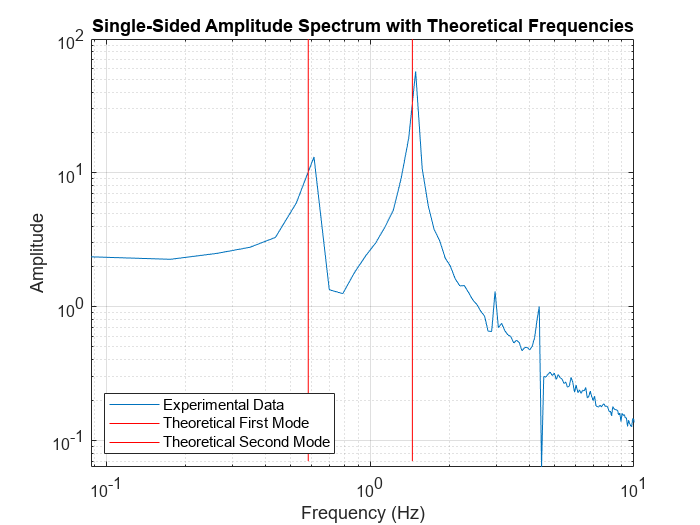

% Plot frequency response
figure();
loglog(f_pos(2:end),2*abs(X_pos(2:end)));
hold on; 
loglog([W2(1) W2(1)], [7e-2 1e2], 'red');
loglog([W2(2) W2(2)], [7e-2 1e2], 'red');
xlim([0 10]);
grid on;
xlabel('Frequency (Hz)');
ylabel('Amplitude');
lgd = legend("Experimental Data", "Theoretical First Mode", "Theoretical Second Mode", "Location", "southwest");
title('Single-Sided Amplitude Spectrum with Theoretical Frequencies');
print('ExampleFFTwithTheory.png', '-dpng', '-r300');